# Preparing Test Signals

%{
clear();

load("test_signal\NopacingChirp2.mat");
TimeArr = data{1}{1}.Values.Time

TimeArr =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090



Inp_Chirp15Hz1 = data{1}{1}.Values.Data;
Measure_Chirp15Hz1 = data{1}{2}.Values.Data;

Inp_Chirp10Hz1 = data{3}{1}.Values.Data;
Measure_Chirp10Hz1 = data{3}{2}.Values.Data;

load("test_signal\NopacingChirp.mat");

Inp_Chirp05Hz1 = data{1}{1}.Values.Data;
Measure_Chirp05Hz1 = data{1}{2}.Values.Data;

Inp_Chirp04Hz1 = data{3}{1}.Values.Data;
Measure_Chirp04Hz1 = data{3}{2}.Values.Data;

Inp_Chirp03Hz1 = data{5}{1}.Values.Data;
Measure_Chirp03Hz1 = data{5}{2}.Values.Data;

Inp_Chirp02Hz1 = data{7}{1}.Values.Data;
Measure_Chirp02Hz1 = data{7}{2}.Values.Data;

Inp_Chirp01Hz1 = data{9}{1}.Values.Data;
Measure_Chirp01Hz1 = data{9}{2}.Values.Data;

Inp_test_signals = {
    Inp_Chirp15Hz1,
    Inp_Chirp10Hz1,
    Inp_Chirp05Hz1,
    Inp_Chirp04Hz1,
    Inp_Chirp03Hz1,
    Inp_Chirp02Hz1,
    Inp_Chirp01Hz1
}

Inp_test_signals = 7×1 cell array
    {60001×1 double}
    {60001×1 double}
    {60001×1 double}
    {60001×1 double}
    {60001×1 double}
    {60001×1 double}
    {60001×1 double}



Measure_test_signals = {
    Measure_Chirp15Hz1,
    Measure_Chirp10Hz1,
    Measure_Chirp05Hz1,
    Measure_Chirp04Hz1,
    Measure_Chirp03Hz1,
    Measure_Chirp02Hz1,
    Measure_Chirp01Hz1
}

Measure_test_signals = 7×1 cell array
    {60001×1 single}
    {60001×1 single}
    {60001×1 single}
    {60001×1 single}
    {60001×1 single}
    {60001×1 single}
    {60001×1 single}



Test_signal_names = {
    'Chirp15Hz1',
    'Chirp10Hz1',
    'Chirp05Hz1',
    'Chirp04Hz1',
    'Chirp03Hz1',
    'Chirp02Hz1',
    'Chirp01Hz1'
};


save("test_signal\Test_Dataframe.mat")
%}

load("test_signal\Test_Dataframe.mat");

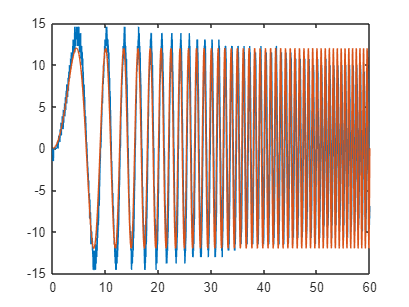

% Plot
figure(Name='Validation Testing Signal')
plot(TimeArr,Measure_Chirp15Hz1,TimeArr,Inp_Chirp15Hz1)

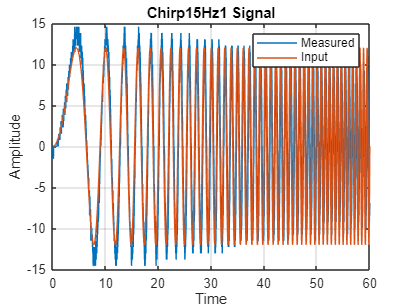

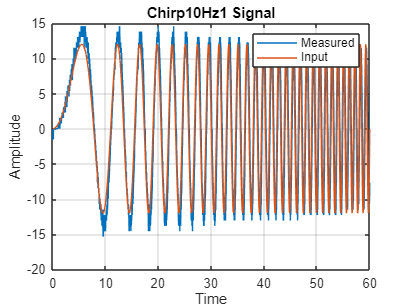

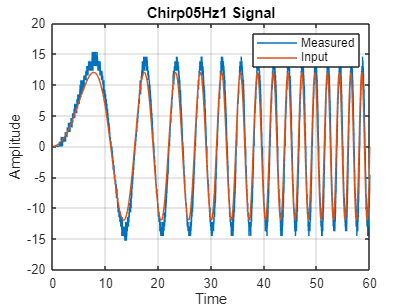

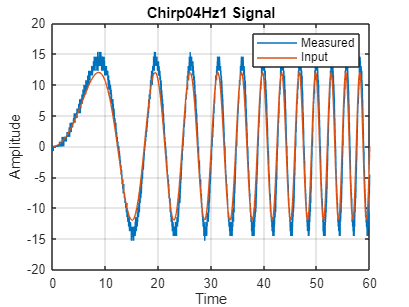

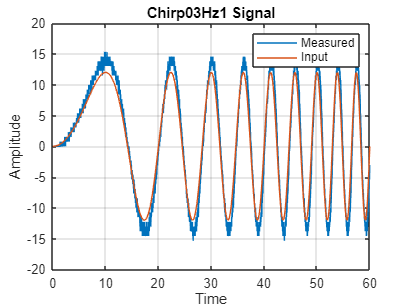

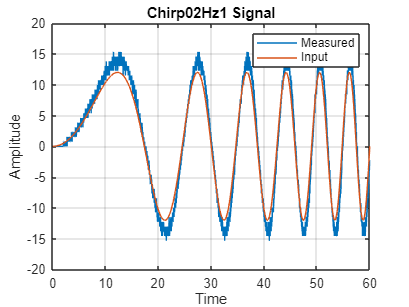

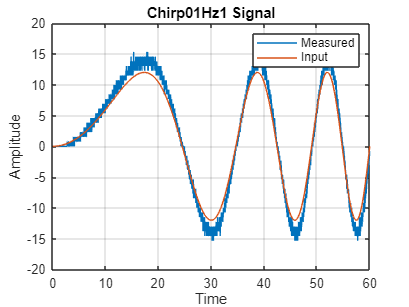


% Loop through each test signal and plot in a separate figure
for i = 1:length(Test_signal_names)
    figure('Name', [Test_signal_names{i}, ' Signal']);
    plot(TimeArr, Measure_test_signals{i}, TimeArr, Inp_test_signals{i});
    title([Test_signal_names{i}, ' Signal']);
    legend('Measured', 'Input');
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
end

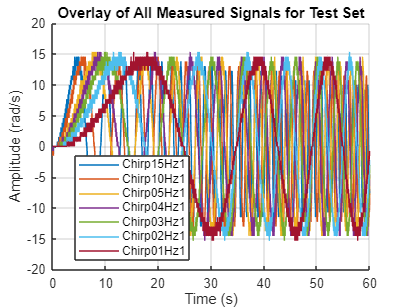


% Final "Conclusion" graph (all measured signals in one plot)
figure('Name', 'Conclusion: Overlay of All Measured Signals');
hold on;
for i = 1:length(Test_signal_names)
    plot(TimeArr, Measure_test_signals{i});
end
hold off;
title('Overlay of All Measured Signals for Test Set');
legend(Test_signal_names, 'Location', 'best');
xlabel('Time (s)');
ylabel('Amplitude (rad/s)');
grid on;

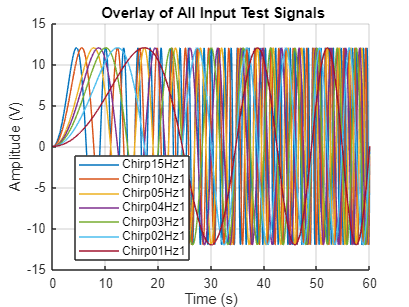


% Final "Conclusion" graph (all measured signals in one plot)
figure('Name', 'Conclusion: Overlay of All Input Test Signals');
hold on;
for i = 1:length(Test_signal_names)
    plot(TimeArr, Inp_test_signals{i});
end
hold off;
title(' Overlay of All Input Test Signals');
legend(Test_signal_names, 'Location', 'best');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

load("model_predict\predict_sin01.mat");

Error using load
Unable to find file or directory 'model_predict\predict_sin01.mat'.

%model_predict_signals = data.Data
model_predict_signals = {data.Data(:, 1), 
                        data.Data(:, 2),
                        data.Data(:, 3),
                        data.Data(:, 4),
                        data.Data(:, 5)}

## Plot input test, measure, predict and Compare


% Define colors for better visibility
colors = {'b', 'r', 'g'}; % Blue for input, Red for measured, Green for model prediction

% Loop through each test signal and plot with model predictions
for i = 1:length(Test_signal_names)
    figure('Name', [Test_signal_names{i}, ' Comparison']);
    
    % Plot Input Test Signal
    plot(TimeArr, Inp_test_signals{i}, 'Color', colors{1}, 'LineWidth', 1.5);
    hold on;
    
    % Plot Measured Signal
    plot(TimeArr, Measure_test_signals{i}, 'Color', colors{2}, 'LineWidth', 1.5);
    
    % Plot Model Predicted Signal
    plot(TimeArr, model_predict_signals{i}, 'Color', colors{3}, 'LineWidth', 1.5);
    
    % Add Title and Legend
    title([Test_signal_names{i}, ' - Input vs Measured vs Predicted']);
    legend('Input Signal', 'Measured Signal', 'Predicted Signal', 'Location', 'best');
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
    hold off;
end

% Function to compute R-squared
function R_squared = compute_rsquare(y_actual, y_pred)
    % Ensure input vectors are column vectors
    y_actual = y_actual(:);
    y_pred = y_pred(:);
    
    % Compute SSE (Sum of Squared Errors)
    SSE = sum((y_actual - y_pred).^2);
    
    % Compute SStot (Total Sum of Squares)
    SS_tot = sum((y_actual - mean(y_actual)).^2);
    
    % Compute R-squared
    R_squared = 1 - (SSE / SS_tot);
end

compute_rsquare(Measure_test_signals{1}, model_predict_signals{1})

% Compute R-squared for each signal type
R_squared_values = zeros(1, length(Test_signal_names));

fprintf('R-squared values for each test signal:\n');
for i = 1:length(Test_signal_names)
    R_squared_values(i) = compute_rsquare(Measure_test_signals{i}, model_predict_signals{i});
    fprintf('%s: %.4f\n', Test_signal_names{i}, R_squared_values(i));
end